 We will now look at a more general robots.  The Toolbox comes with several robot models

clear
load exampleRobots
whos

  Name        Size            Bytes  Class                     Attributes

  baxter      1x1                 8  robotics.RigidBodyTree              
  lbr         1x1                 8  robotics.RigidBodyTree              
  puma1       1x1                 8  robotics.RigidBodyTree              
  puma2       1x1                 8  robotics.RigidBodyTree              



and includes the Puma robot and a 2-armed Baxter model. Details of the Baxter model are given by

baxter.showdetails()

--------------------
Robot: (48 bodies)

 Idx                         Body Name                      Joint Name                      Joint Type                         Parent Name(Idx)   Children Name(s)
 ---                         ---------                      ----------                      ----------                         ----------------   ----------------
   1             collision_head_link_1                collision_head_1                           fixed                                  base(0)   
   2             collision_head_link_2                collision_head_2                           fixed                                  base(0)   
   3                             torso                        torso_t0                           fixed                                  base(0)   left_torso_itb(4)  right_torso_itb(5)  pedestal(6)  head(7)  sonar_ring(12)  right_arm_mount(13)  left_arm_mount(31)  
   4                    left_torso_itb            left_torso_itb_fixed    

and we see a total of 48 links.  The torso (the third rigid body) has 7 children and is an example of a branched structure.  We can extract a sub tree

baxter.subtree('right_arm_mount')

ans =   RigidBodyTree with properties:

    NumBodies: 18
       Bodies: {1×18 cell}
    BodyNames: {1×18 cell}
     BaseName: 'base'


which we can treat as a regular robot arm.

For the next example we will focus on the classical Puma 560, and the model puma1 is based on a standard Denavit-Hartenberg representation, where the link frames are not neccessarly on the robot

puma1.showdetails()

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1           L1         jnt1     revolute             base(0)   L2(2)  
   2           L2         jnt2     revolute               L1(1)   L3(3)  
   3           L3         jnt3     revolute               L2(2)   L4(4)  
   4           L4         jnt4     revolute               L3(3)   L5(5)  
   5           L5         jnt5     revolute               L4(4)   L6(6)  
   6           L6         jnt6     revolute               L5(5)   
--------------------


We can plot it in its home configuration

q = puma1.homeConfiguration

q =   1×6 struct array with fields:

    JointName
    JointPosition


puma1.show(q)

ans =   Axes with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


and we see a skeleton of the robot in its 'ready' configuration.

Forward kinematics is simply

puma1.getTransform(q, 'L6')

ans =     1.0000         0         0    0.4521
         0    1.0000         0   -0.1500
         0         0    1.0000    0.4318
         0         0         0    1.0000


A key problem with arm robots is inverse kinematics.  We will define an arbitrary pose for our Puma robot with its end-effector pointing downward

T = trvec2tform([0.4 0.4 0.2]) * eul2tform([0 0 pi],'ZYX')

T =     1.0000         0         0    0.4000
         0   -1.0000   -0.0000    0.4000
         0    0.0000   -1.0000    0.2000
         0         0         0    1.0000


Next we define an inverse kinematics solver object

ik = robotics.InverseKinematics('RigidBodyTree', puma1);

and define some parameters such as the weights to be applied to errors in the 6 Cartesian degrees of freedom and the initial solution

weights = ones(6,1);
q0 = puma1.homeConfiguration;

We then pass the various parameters to the solver object

[q, info] = ik('L6', T, weights, q0);
info

info =         NumIterations: 41
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8333e-08
             ExitFlag: 1
               Status: 'success'


and we see that it has been successfuly solved with a very small pose residual.  The configuration of the robot can be visualized by

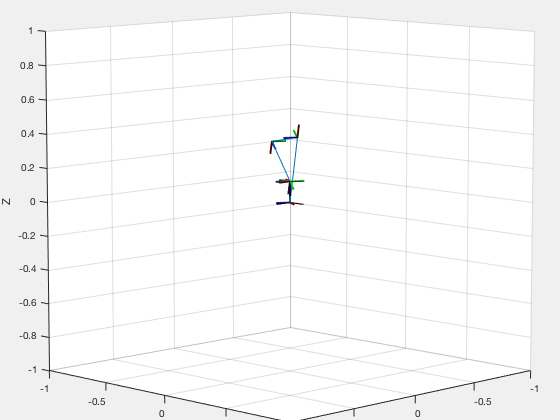

puma1.show(q);